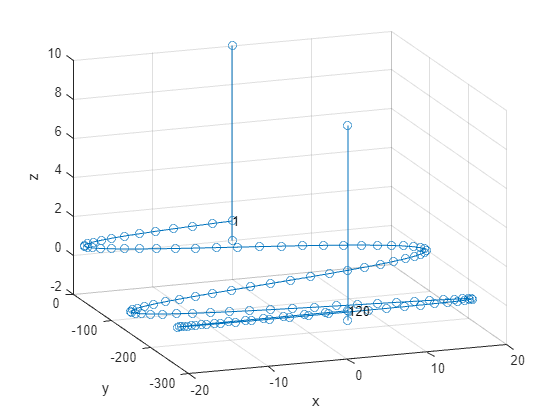

clear

hoverAltitude = 10;
numWaypoints = 120;
xSweep = -300;
ySweep = 40;
zSweep = 2;

playerStart = [0 0 0];
playerEnd = [0 xSweep 0];

xx = linspace(0, xSweep, numWaypoints)';
wayPoints = [  ((ySweep/2).*sind(3.*xx)) xx ((zSweep/2).*cosd(xx))];


flightPath = [
    playerStart;
    playerStart(1,1) playerStart(1,2) hoverAltitude;
    wayPoints;
    playerEnd(1,1) playerEnd(1,2) hoverAltitude;
    playerEnd
    ];

figure;
hold on
grid on
xlabel x
ylabel y
zlabel z
    plot3(flightPath(:,1), flightPath(:,2), flightPath(:,3),'o-')
    for p=[1 length(wayPoints)]
        text(wayPoints(p,1), wayPoints(p,2), wayPoints(p,3), num2str(p))
    end
view(-20, 20)
hold off

% Create or open a text file for writing
fileID = fopen('waypoints.txt', 'w');

% Write the initial line
fprintf(fileID, 'waypoints = [\n');

% Loop through each row of wayPoints and write cmdString to the file
for i = 1:numWaypoints
    cmdString = ['    airsim.Vector3r(' num2str(wayPoints(i, 1)) ',' num2str(wayPoints(i, 2)) ', -z - ' num2str(wayPoints(i, 3)) '),'];
    if i == numWaypoints
        cmdString = ['    airsim.Vector3r(' num2str(wayPoints(i, 1)) ',' num2str(wayPoints(i, 2)) ', -z -' num2str(wayPoints(i, 3)) ')'];
    end
    fprintf(fileID, '%s\n', cmdString);
end

% Close the file and add the closing square bracket
fprintf(fileID, ']\n');
fclose(fileID);